# Chapter 4, Section 3 (Part 3)

The goal of this activity is to introduce the inverse of a linear transformation. Let's start with a theorem that we will need.

# Theorem

Let $B=\{\vec v_1,\ \ldots,\ \vec v_n\}$ be a basis for a vector space $V$. If $T:\, V\rightarrow \mathbb R^n$ is the coordinate transformation function $T(\vec v)=[\vec v]_B$, then $T$ is an isomorphism.

**Proof:** Let $\vec u,\ \vec v\in V$. Then they can both be written as linear combinations of the basis vectors in $B$,


$$\begin{array}{rcl}
\vec u&=&c_1\vec v_1+\cdots+c_n\vec v_n\\
\vec v&=&d_1\vec v_1+\cdots+ d_n\vec v_n
\end{array}$$


and


$$\vec u+\vec v=(c_1+d_1)\vec v_1+\cdots+(c_n+d_n)\vec v_n$$


Therefore, we can write:


$$\begin{array}{rcl}
T(\vec u+\vec v)&=&\pmatrix{c_1+d_1\cr \vdots\cr c_n+d_n}\\
&=&\pmatrix{c_1\cr \vdots\cr c_n}+\pmatrix{d_1\cr \vdots\cr d_n}\\
&=&T(\vec u)+T(\vec v)
\end{array}$$


If $r\in \mathbb R$, then 


$$r\vec u=(rc_1)\vec v_1+\cdots+(rc_n)\vec v_n$$


so we can write:


$$\begin{array}{rcl}
T(r\vec u)&=&\pmatrix{rc_1\cr \vdots\cr rc_n}\\
&=&r\pmatrix{c_1\cr \vdots\cr c_n}\\
&=&r(T(\vec u))
\end{array}$$


Because  $T(\vec u+\vec v)=T(\vec u)+T(\vec v)$ and $T(r\vec u)=rT(\vec u)$, we've shown that the coordinate mapping is a linear transformation. 

Now, is it one-to-one? Let's show that $N(T)=\{\vec 0\}$.  Let $\vec u\in N(T)$, then $\vec u\in V$ and $T(\vec u)=\vec 0$. Because $B=\{\vec v_1,\ \ldots,\ \vec v_n\}$ is a basis for $V$, we know that $\vec u$ is a linear combination of these basis vectors.


$$\vec u=c_1\vec v_1+\cdots+c_n\vec v_n$$


Hence, $[\vec u]_B=(c_1, c_2, ... , c_n)^T$. Because $T(\vec u)=\vec 0$, we can write:


$$\begin{array}{rcl}
T(\vec u)&=&\vec 0\\
[\vec u]_B&=&\vec 0\\
\pmatrix{c_1\cr \vdots\cr c_n}&=&\pmatrix{0\cr \vdots\cr 0}
\end{array}$$


Therefore, $c_1=0,\ \ldots,\ c_n=0$; that is, all the coefficients are zero. This means that 


$$\begin{array}{rcl}
\vec u&=&c_1\vec v_1+\cdots+c_n\vec v_n\\
\vec u&=&0\vec v_1+\cdots+0\vec v_n\\
\vec u&=&\vec 0
\end{array}$$


Thus, we've shown that any vector in $N(T)$ is the zero vector, so $N(T)=\{\vec 0\}$.  Therefore, $T$ is a one-to-one linear transformation.

Is $T$ onto $\mathbb R^n$? Let $\vec w\in \mathbb R^n$. Then,


$$\vec w=\pmatrix{w_1\cr\vdots\cr w_n}$$


As $B=\{\vec v_1,\ \ldots,\ \vec v_n\}$ is a basis for $V$, if we let 


$$\vec u=w_1\vec v_1+\cdots+w_n\vec v_n$$


then:


$$T(\vec u)=[\vec u]_B=\pmatrix{w_1\cr \vdots\cr w_n}
$$


So we've shown that there is a vector $\vec u\in V$ such that $T(\vec u)=\vec w$. Therefore, $T:\,V\rightarrow \mathbb R^n$ is onto $\mathbb R^n$. 

Because we've shown that $T:\,V\rightarrow \mathbb R^n$ is a linear transformation that is one-to-one and onto $\mathbb R^n$, we've proven that $T$ is an isomorphism.

# Inverse of a Linear Transformation

Now we will see why we proved the theorem above. 

**Definition:** Let $V$ and $W$ be vector spaces and $T:\,V\rightarrow W$ a one-to-one linear transformation. The mapping $T^{-1}:\,R(T)\rightarrow V$ is defined by


$$T^{-1}(\vec w)=\vec v\qquad\text{if and only if}\qquad T(\vec v)=\vec w$$


is called the **inverse** of $T$.

The statement $T^{-1}(\vec w)=\vec v$ if and only if $T(\vec v)=\vec w$ is an "if and only if" statement, so it means two things:

- If $T^{-1}(\vec w)=\vec v$, then $T(\vec v)=\vec w$.

- If $T(\vec v)=\vec w$, then $T^{-1}(\vec w)=\vec v$.

Now, before we prove an important theorem, Let's create an image that shows the meaning of $T^{-1}(\vec w)=\vec v$ if and only if $T(\vec v)=\vec w$.

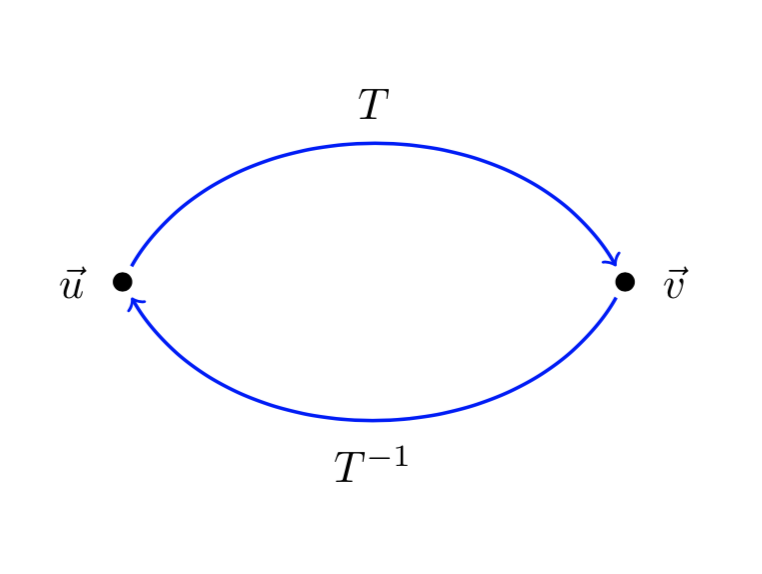

# Example #1

Note in the diagram that each mapping reverses what the other does; $T$ sends $\vec u$ to $\vec v$, so $T^{-1}$ sends $\vec v$ back to $\vec u$. You might remember from algebra that one way to find the inverse of a function is to replace $f(x)$ with $y$,  switch $x$ and $y$, then solve for $y$. For example, if $f(x)=2x+3$, then we can write:


$$\begin{array}{rcl}
f(x)&=&2x+3\\
y&=&2x+3
\end{array}$$


Now we can switch $x$ and $y$ and solve for $y$.


$$\begin{array}{rcl}
x&=&2y+3\\
x-3&=&2y\\
y&=&\frac{x-3}{2}
\end{array}$$


Therefore, the inverse of the function $f(x)=2x+3$ is $f^{-1}(x)=\frac{x-3}{2}$. Now, does this work? Let's test it in Matlab. We'll first define the anonymous function f and finv.

f=@(x) 2*x+3;
finv=@(x) (x-3)/2;

Now, note that:

f(5)

ans = 13

Now, finv should return 13 to 5.

finv(13)

ans = 5

We can compose them to also see that this works.

finv(f(5))

ans = 5

Yes, starts at 5 and returns to 5.

f(finv(13))

ans = 13

Yes, starts at 13 and returns to 13. Note that we've shown that:


$$f^{-1}(f(x))=x\qquad\text{and}\qquad f(f^{-1}(y))=y$$


This is also true with our linear transformation because it is one-to-one.


$$T^{-1}(T(\vec u))=\vec u\qquad\text{and}\qquad T(T^{-1}(\vec v))=\vec v$$


Now we can prove a theorem.

# Theorem

If $V$ and $W$ are vectors spaces and $T:\, V\rightarrow W$ a one-to-one linear transformation, then $T^{-1}:\, R(T)\rightarrow V$ is also a linear transformation. 

**Proof:** Let $V$ and $W$ be vectors spaces and let $T:\, V\rightarrow W$ be a one-to-one linear transformation. Then, by what we showed above, the inverse exists. To show that $T^{-1}:\ R(T)\rightarrow  V$ is a linear transformation, we need to show two things:

- $T^{-1}(\vec w_1+\vec w_2)=T^{-1}(\vec w_1)+T^{-1}(\vec w_2)$ for all $\vec w_1, \vec w_2\in R(T)$.

- $T^{-1}(c\vec w)=cT^{-1}(\vec w)$ for all $\vec w\in R(T)$ and $c\in \mathbb R$.

**Part 1:** Let $\vec w_1, \vec w_2\in R(T)$. Then there exists $\vec v_1, \vec v_2\in V$ such that:


$$T(\vec v_1)=\vec w_1\qquad\text{and}\qquad T(\vec v_2)=\vec w_2$$


Note that this means that:


$$T^{-1}(\vec w_1)=\vec v_1\qquad\text{and}\qquad T^{-1}(\vec w_2)=\vec v_2$$


Because $T$ is a linear transformation, we can write:


$$\begin{array}{rcl}
T(\vec v_1+\vec v_2)&=&T(\vec v_2)+T(\vec v_2)\\
T(\vec v_1+\vec v_2)&=&\vec w_1+\vec w_2
\end{array}$$


Therefore, by our discussion of the inverse above (see our image), we know that:


$$T^{-1}(\vec w_1+\vec w_2)=\vec v_1+\vec v_2$$


But $\vec v_1=T^{-1}(\vec w_1)$ and $\vec v_2=T^{-1}(\vec w_2)$, so this last equation is equivalent to:


$$T^{-1}(\vec w_1+\vec w_2)=T^{-1}(\vec w_1)+T^{-1}(\vec w_2)$$


**Part 2: **Let $\vec w\in R(T)$. This means that there exists a $\vec v\in V$ such that


$$T(\vec v)=\vec w\qquad\text{and}\qquad T^{-1}(\vec w)=\vec v$$


Let $c\in \mathbb R$. Because $T$ is a linear transformation, we can write:


$$\begin{array}{rcl}
T(\vec v)&=&\vec w\\
cT(\vec v)&=&c\vec w\\
T(c\vec v)&=&c\vec w
\end{array}$$


Because $T^{-1}$ is the inverse of $T$, this means that:


$$\begin{array}{rcl}
T^{-1}(c\vec w)&=&c\vec v\\
T^{-1}(c \vec w)&=&cT^{-1}(\vec w)
\end{array}$$


**Conclusion:** Because we've shown that both part 1 and part 2 are true, we've shown that $T^{-1}$ is a linear transformation. 

# Example #2:

Given that $A$ is an $n\times n$ invertible matrix and $T:\,\mathbb R^n\rightarrow \mathbb R^n$ is a linear transformation defined by $T(\vec x)=A\vec x$, determine the linear transformation $T^{-1}$.

**Solution:** Let's use the technique we were reminded of in Example #1. Start with


$$T(\vec x)=A\vec x$$


replace $T(\vec x)$ with $\vec y$,


$$\vec y=A\vec x$$


then switch $\vec x$ and $\vec y$ and solve for $\vec y$.


$$\begin{array}{rcl}
\vec x&=&A\vec y\\
A^{-1}\vec x&=&A^{-1}(A\vec y)\\
A^{-1}\vec x&=&(A^{-1}A)\vec y\\
A^{-1}\vec x&=&I\vec y\\
A^{-1}\vec x&=&\vec y
\end{array}$$


Therefore, 


$$T^{-1}(\vec x)=A^{-1}\vec x$$


# Example #3

Let $T:\,\mathbb R^2\rightarrow \mathbb R^2$ be defined by $T(\vec x)=A\vec x$, where


$$T\left(\pmatrix{x\cr y}\right)=\pmatrix{1 & 3\cr 1 & 4}\pmatrix{x\cr y}$$


Perform each of the following tasks:

- Show that $T$ is an isomorphism.

- Find $A^{-1}$.

- Show directly that $T^{-1}(\vec w)=A^{-1}\vec w$ is the inverse of $T(\vec x)=A\vec x$.

**Solution: **

**Part 1: **In our previous activity, we proved that if $A$ is invertible, then $T(\vec x)=A\vec x$ is an isomorphism. Let's calculate the determinant of matrix $A$.


$$\begin{array}{rcl}
\left|\matrix{1 & 3\cr 1 & 4}\right|&=&4-3=1
\end{array}$$


We can check this with Matlab.

A=[1 3;1 4];
det(A)

ans = 1

Same answer. Because $\text{det}(A)\ne 0$, matrix $A$ is invertible. Therefore, $T$ is an isomorphism.

**Part 2: **The inverse is:


$$\begin{array}{rcl}
A^{-1}&=&\frac{1}{(1)(4)-(1)(3)}\pmatrix{4 & -3\cr -1 & 1}\\
A^{-1}&=&\pmatrix{4 & -3\cr -1 & 1}
\end{array}$$


We can check this with Matlab.

Ainv=inv(A)

Ainv =      4    -3
    -1     1


**Part 3: **Our definition of the inverse says that $T^{-1}$ is the inverse of $T$ provided that


$$T^{-1}(\vec w )=\vec v\qquad\text{if and only if}\qquad T(\vec v)=\vec w$$


Let $\vec w=\pmatrix{x\cr y}\in \mathbb R^2$. Because $T^{-1}(\vec w)=A^{-1}\vec w$, we can write:


$$\begin{array}{rcl}
T^{-1}\left(\pmatrix{x\cr y}\right)&=&\pmatrix{4 & -3\cr -1 & 1}\pmatrix{x\cr y}\\
&=&\pmatrix{4x-3y\cr -x+y}
\end{array}$$


Now we will see if $T$ returns this answer to $\pmatrix{x\cr y}$.


$$\begin{array}{rcl}
T\left(\pmatrix{4x-3y\cr -x+y}\right)&=&\pmatrix{1 & 3\cr 1 & 4}\pmatrix{4x-3y\cr -x+y}\\
&=&\pmatrix{1(4x-3y)+3(-x+y)\cr 1(4x-3y)+4(-x+y)}\\
&=&\pmatrix{4x-3y-3x+3y\cr 4x-3y-4x+4y}\\
&=&\pmatrix{x\cr y}
\end{array}$$


That worked. We can check this with Matlab.

syms x y
T=@(x) A*x;
Tinv=@(x) Ainv*x;
Tinv([x;y])

$$ans = \left(\begin{array}{c} 4\,x-3\,y\\ y-x \end{array}\right)$$

OK. Now,

T(Tinv([x;y]))

$$ans = \left(\begin{array}{c} x\\ y \end{array}\right)$$

Same as our hand-calculations. We'll leave it to our readers to show that if $T(\vec u)=\vec w$, then $T^{-1}(\vec w)=\vec u$, but we'll show it works with Matlab.

T([x;y])

$$ans = \left(\begin{array}{c} x+3\,y\\ x+4\,y \end{array}\right)$$

OK. Now,

Tinv(T([x;y]))

$$ans = \left(\begin{array}{c} x\\ y \end{array}\right)$$

Back to $\pmatrix{x\cr y}$ again, so we've shown directly that $T^{-1}(\vec x)=A^{-1}\vec x$ is the inverse of $T(\vec x)=A\vec x$.

# Important Theorem

If $V$ and $W$ are vector spaces of dimension $n$, then $V$ and $W$ are isomorphic.

**Proof:** To show that this is true, we must find a linear transformation $\phi:\, V\rightarrow W$ that is one-to-one and onto $W$. Let's start with an image.

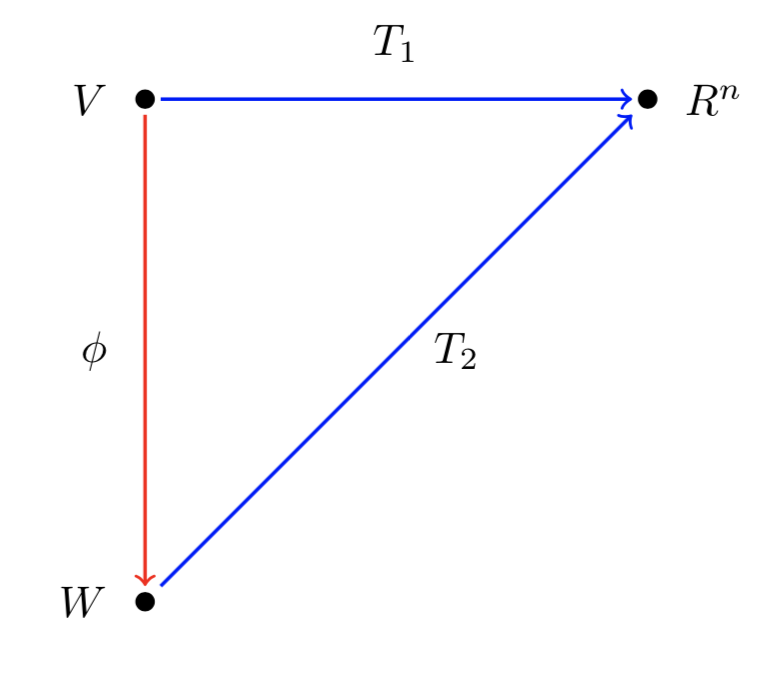

Because $\text{dim}(V)=n$ and $\text{dim}(\mathbb R^n)=n$, we've previously shown that $V$ and $\mathbb R^n$ are isomorphic, so we know there exists a linear transformation $T_1:V\rightarrow \mathbb R^n$ that is one-to-one and onto $\mathbb R^n$. Because $\text{dim}(W)=n$ and $\text{dim}(\mathbb R^n)=n$, we've shown that $W$ and $\mathbb R^n$ are isomorphic, so we know there exists a linear transformation $T_2:W\rightarrow \mathbb R^n$ that is one-to-one and onto $\mathbb R^n$. 

Now, here is a little algebra review. Suppose that the function $f(x)$ is a one-to-one function. Then we know its inverse exists. Is the inverse one-to-one? Set


$$\begin{array}{rcl}
f^{-1}(x)&=&f^{-1}(y)\\
\end{array}$$
 

then take $f$ of both sides.


$$\begin{array}{rcl}
f(f^{-1}(x))&=&f(f^{-1}(y))\\
x&=&y
\end{array}$$


Therefore, $f^{-1}$ is one-to-one. Because $T_2$ is a one-to-one linear transformation, we've shown that its inverse $T_2^{-1}$ is also a linear transformation. Let's do another image.

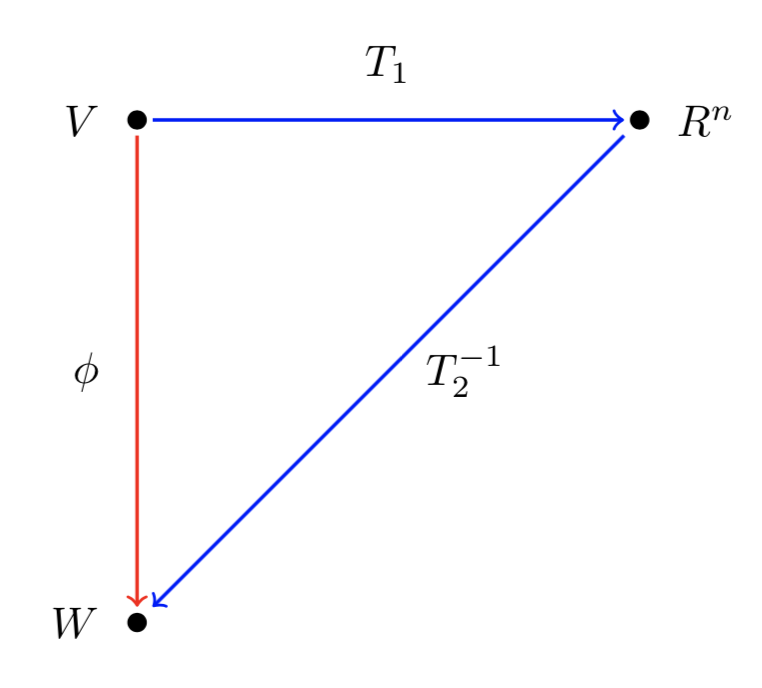

We've shown that if we have two linear transformations, then their composition is also a linear transformation. So, we will define $\phi$ as the composition of $T_2^{-1}$ and $T_1$; that is,


$$\phi=T_2^{-1}\circ T_1$$


So we know that $\phi:V\rightarrow W$ is a linear transformation. Now, is it one-to-one? Suppose that


$$\phi(\vec v_1)=\phi(\vec v_2)$$


then this means that:


$$\begin{array}{rcl}
(T_2^{-1}\circ T_1)(\vec v_1)&=&(T_2^{-1}\circ T_1)(\vec v_2)\\
T_2^{-1}(T_1(\vec v_1))&=&T_2^{-1}(T_1(\vec v_2))
\end{array}$$


Now, because $T_2^{-1}$ is one-to one, this means that


$$T_1(\vec v_1)=T_1(\vec v_2)$$


and because $T_1$ is one-to-one, this means that:


$$\vec v_1=\vec v_2$$


Thus, we've shown that $\phi$ is a one-to-one linear transformation. 

Now, is $\phi$ onto $W$? Let $\vec w\in W$. Then $T_2(\vec w)\in \mathbb R^n$ (see our first image). Because $T_1$ is onto $\mathbb R_n$, there exists a $\vec v\in V$ such that 


$$T_1(\vec v)=T_2(\vec w)$$


Because $T_2$ is invertible, this means that


$$\begin{array}{rcl}
T_2^{-1}(T_1(\vec v))&=&\vec w\\
(T_2^{-1}\circ T_1)(\vec v))&=&\vec w\\
\phi(\vec v)&=&\vec w
\end{array}$$


Therefore, $\phi$ maps $V$ onto $W$. Because we have shown that $\phi:V\rightarrow W$ is a one-to-one and onto linear transformation, $\phi$ is an isomorphism. Hence, we've proved that $V$ and $W$ are isomorphic.

# Why is an Iphomorphism Important?

We've see that if $T:V\rightarrow W$ is an isomorphism, then $V$ and $W$ are isomorphic. But why is this important? There are no examples of this importance in our textbook, so let's look at an example.

# Example #4

We've shown that $T:P_2\rightarrow \mathbb R^3$ is an isomorphism, so $P_2$ and $\mathbb R^3$ are isomorphic. Now, here is a question. Is the collection $S=\{1+x,\ 2+x^2,\ 1+2x+x^2\}$ of polynomials in $P_2$ linearly independent?

**Solution:** Normally, we would proceed by setting up the linear combination


$$c_1(1+x)+c_2(2+x^2)+c_3(1+2x+x^2)=0$$


and solve for $c_1$, $c_2$, and $c_3$ as follows:


$$\begin{array}{rcl}
c_1+c_1x+2c_2+c_2x^2+c_3+2c_3x+c_3x^2&=&0\\
(c_1+2c_2+c_3)+(c_1+2c_3)x+(c_2+c_3)x^2&=&0+0x+0x^2
\end{array}$$


Then we compare the coefficients, which gives us a system of three equations.


$$\begin{array}{rcl}
c_1+2c_2+c_3&=&0\\
c_1+2c_3&=&0\\
c_2+c_3&=&0
\end{array}$$


Then we set up the augmented matrix


$$\pmatrix{1 & 1 & 1 & 0\cr 1 & 0 & 2 & 0\cr 0 & 1 & 1 & 0}$$


and row reduce to find $c_1$, $c_2$, and $c_3$.

A=[1 1 1;1 0 2;0 1 1];
rref([A,zeros(3,1)])

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0


Thus, $c_1=c_2=c_3=0$ and the set $S=\{1+x,\ 2+x^2,\ 1+2x+x^2\}$ is linearly independent.

**Much Quicker Way:** If we use the ordered basis $B=\{1,x,x^2\}$ for $P_2$ and the standard basis $E=\{\textbf e_1,\ \textbf e_2,\ \textbf e_3\}$ for $\mathbb R^3$, then it is easily seen that that the coordinates of $1+x$, $2+x^2$, and $1+2x+x^2$, without doing any work, are:


$$[1+x]_E=\pmatrix{1\cr1\cr0},\qquad [2+x^2]_E=\pmatrix{2\cr 0\cr 1}\qquad\text{and}\qquad  [1+2x+x^2]_E=\pmatrix{1\cr 2\cr 1}$$


Because $P_2$ and $\mathbb R^3$ are isomorphic, the collection $S=\{1+x,\ 2+x^2,\ 1+2x+x^2\}$ is linearly independent if and only if $[1+x]_E$, $[2+x^2]_E$, and $[1+2x+x^2]_E$ are linearly independent. To see if $[1+x]_E$, $[2+x^2]_E$, and $[1+2x+x^2]_E$  are linearly independent, we set up the following matrix.


$$\pmatrix{1 & 1 & 1 & 0\cr 1 & 0 & 2 & 0\cr 0 & 1 & 1 & 0}$$


What? The same thing we got doing it the other way? Aha! Much quicker way. :-)